# 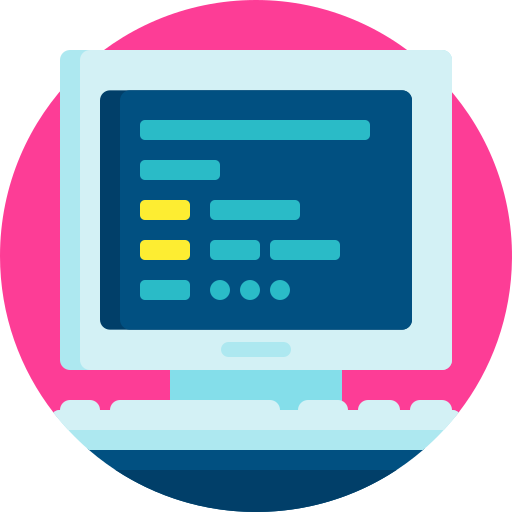

# Project: Altitude control of a Flappy Bird robot

## PeopleSoft number

Insert your PeopleSoft number below and run this section before proceeding. You will need to run this section every time you reopen this project so that your PeopleSoft numbers reloaded to the MATLAB workspace.

peopleSoftNumber = 1234567 %enter your student PeopleSoft number

peopleSoftNumber = 1234567

Your student number will be used to allocate you unique Flappy Bird parameters — each student will have a different system and you will be marked against your particular system. Therefore, copying another student's controller is likely to end in misery!

## Project overview

You are tasked with designing an altitude (height) controller for a Flappy Bird robot. We are going to assume the robot only has a single controllable degree of freedom (that being up and down) and has a controlled constant lateral (forward) velocity that we do not need to worry about. As in the original game, the Flappy Bird robot will be required to move through a series of obstacles, with ever decreasing space allowance — see the gif below.

**GIF OF FLAPPY BIRD MOVING THROUGH OBSTACLES**

**Figure 1**: Image of Flappy Bird robot in action.

The Flappy Bird's wings produce a controllable thrust that is used to move the robot up and down. The wings cannot instantaneously produce a thrust due to their inherent dynamics, and instead, after a constant, non-negligible delay, generates the commanded thrust. 

A constant gravitational force acts on the Flappy Bird robot, which the controller needs to overcome in order to prevent the robot from falling to the ground. Additionally, aerodynamic drag, proportional to the robot's vertical velocity, affects the system response.

You are provided with the simplified dynamics of the Flappy Bird robot altitude below:


$$\begin{array}{rl} m a(t) &=f(t-\tau)-mg-bv(t),\\ 
\dot{v}(t) &=a(t),\\
\dot{z}(t) &=v(t),\\
\end{array}$$


where:

- $f(t-\tau)$ is the controllable vertical thrust produced by the wings, in $N$, delayed by an amount $\tau$, in $s$,

- $m$ is the mass of the Flappy Bird robot, in $kg$,

- $g$ is the gravitational acceleration, in $m.s^{-2}$,

- $b$ is the aerodynamic drag coefficient, in $N.s.m^{-1}$,

- $v(t)$ is the vertical velocity of the robot, in $m.s^{-1}$,

- $a(t)$ is the linear acceleration of the robot, in $m.s^{-2}$,

- $z(t)$is the height (altitude) of the robot above ground, in $m$.

We will assume for now that the Flappy Bird robot is initially at rest (on the ground and motionless) and this corresponds with $z(t)=0$. Note that while not explicitly captured in the dynamics above, the simulated Flappy Bird robot is unable to go to negative heights as a result of the ground ($z(t)\geq 0,~\forall t$). 

## Part 1: Modelling and performance specifications

### System modelling

**Part 1** will focus on modelling our quadrotor, followed by determining the requisite closed-loop performance specifications to keep the Flappy Bird robot from crashing into anything. We will need this information in order to move to the control design in **Part 2**. We start by determining a suitable mathematical model of our system, given dynamic knowledge of our system.

#### **  Question 1:** Provide a detailed block diagram of the Flappy Bird robot based on the information provided above. The block diagram must show the mapping from input signal $F(s)$ to the altitude output signal, $Z(s)$, and all system parameters should be represented by blocks or signals, as appropriate.

*    Format: Your answer can be handwritten or completed using a graphical tool and should clearly show all relevant signal and parameter names. *

#### **  Question 2:** Simplify your answer in Question 1 to a two-block system, where one block represents the collective transfer behaviour from $F(s)$ to $Z(s)$ and the other block represents the transfer behaviour from the gravitational acceleration, $G(s)$, to $Z(s)$. Include all working as part of your submission.

*    Format: Your answer can be handwritten or completed using a graphical tool and should clearly show all relevant signal and parameter names. *

### Performance specifications

In order to design an appropriate feedback controller, you will need to determine the requisite performance specifications for the Flappy Bird robot in order to always avoid hitting an obstacle. We will begin by assessing the steady-state error requirements. We desire precision control of the Flappy Bird robot, so we will target zero-error tracking at steady-state to both step-like reference signals and disturbances.

#### **  Question 3:** Given the previously presented dynamic model of the Flappy Bird robot, determine the minimum type number required by the robot's controller in order to fully reject disturbances at steady-state.

We will now focus on the transient design specifications. With reference to Figure 2, our Flappy Bird robot will be issued step commands halfway between each set of obstacles. The goal is for the robot to follow the step commands sufficiently, such that the worst-case overshoot and settling time is adhered to. 

**IMAGE OF FLAPPY BIRD WITH VISUAL SPECS**

**Figure 2**: Image of Flappy Bird robot attempting to traverse through upcoming obstacles.

Figure 2 illustrates the most challenging settling time and overshoot requirement, which implies that if the robot can meet these specifications, then they can meet the less rigorous challenges. 

#### **  Question 4: **Using Figure 2 and the other information provided, determine an appropriate percentage overshoot requirement, $\%OS$, and settling time. 

*Format: Your submission must be a PDF and should include an annotated version of Figure 2 (either used directly or reproduced) to aid in showing your working. The work can be handwritten or completed using a document editor (e.g. Word). *

We will make use of the design procedure as outlined in **Chapter 11** and **Chapter 12** of the course notes. Specifically, we will employ frequency-domain specifications that we can ultimately use to shape our loop transfer $L(s)$ via $G(s)$.

#### **  Question 5: **Determine the 2nd-order reference model, $M_A(s)$, that meets the design specifications from **Question 4**.

*    Format: Your answer should show the necessary working and can be handwritten or mathematically typeset. *

%Add code here for the question (if required)


#### **  Question 6: Determine the corresponding simplified *****stay-above***** and *****stay-below magnitude response bounds (in dB), as well as any relevant frequency point(s) of interest. The information should be presented in a Bode magnitude response plot, showing that ***$|M_A(j\omega)|_{dB}$ adheres to the prescribed bounds.

*     Format: Your answer should be a one-page document that includes both relevant calculations, as well as the clearly annotated Bode magnitude response plot. Note that you can generate the Bode magnitude response plots using MATLAB.*

%Add code here for the question (if required)


## Part 2: Feedback control design

## Performance specifications

Now that we have a parameterised model of our system in **Part 1**, we can proceed with the control design. We begin by defining the closed-loop performance specifications. The high-level objective is to design a feedback control scheme that meets the following specifications for step reference signals, $R_z(s)=\frac{a}{s}$, for the quadrotor altitude:

- **Settling time requirement: **$T_{z_s}\leq5$** seconds,**

- **Overshoot requirement: **$\%OS_z\leq 10\%$**,**

- **Steady-state error requirement: **$e_z(\infty)=0$**.**

- **Control action requirement: **$\min \{F(t)\}$

In other words, we require our quadrotor to reach (and then remain in) the $\pm 2\%$ band around  $r(t)=a, ~\forall t\geq 0$ in less than 5 seconds and it must do so with less than $10\%$ overshoot. Additionally, the tracking error must tend to zero ($z(\infty) \rightarrow a$). The fourth requirement is to minimise the thrust of the propellers (subject to the other constraints). The thrust production is related to the power consumed by the quadrotor and the amount of effort the motors need to do, so it is in our best interest to keep $f(t)$ as small as possible (e.g. to maximise flight time in a real-world scenario). 

## Feedback control scheme

We will make use of a cascaded (minor loop) control scheme to exploit the fact that we have velocity information available. The cascaded loop structure is shown below, where

- $P(s)=\frac{V(s)}{F(s)}$ is the velocity loop plant, when the gravitational force is set to zero,

- $D(s)$ represents the gravitational force disturbance,

- $G_v(s)$ is the inner (velocity) loop controller,

- $G_{z}(s)$ is the outer (altitude) loop controller,

- $R_v(s)$ is the velocity reference signal, and

- $R_z(s)$ is the altitude reference signal.

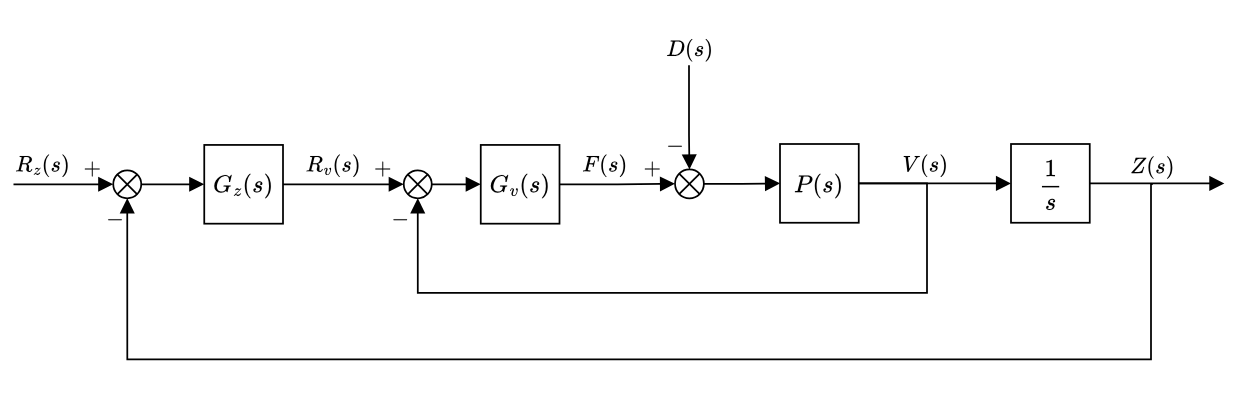

*Figure 3: Block diagram of the cascaded closed-loop quadrotor system. Sensor noise has been excluded from the block diagram for sake of clarity.*

The benefit of the inner loop is that we can perform a control design on a lower order system, whilst also addressing the gravitational disturbance at its source. Note that as the inner loop also excludes the integrator from $V(s)$ to $Z(s)$, hence the inner loop will have additional phase lead (which makes our lives a lot easier) and also allows us to achieve a greater bandwidth for the inner loop.

We will focus on the **inner loop** first, with the intention of isolating and addressing the gravitational disturbance, $D(s)$. Once we design the inner loop, we will then move to the outer loop design. Ignoring everything outside of the inner loop, we get:

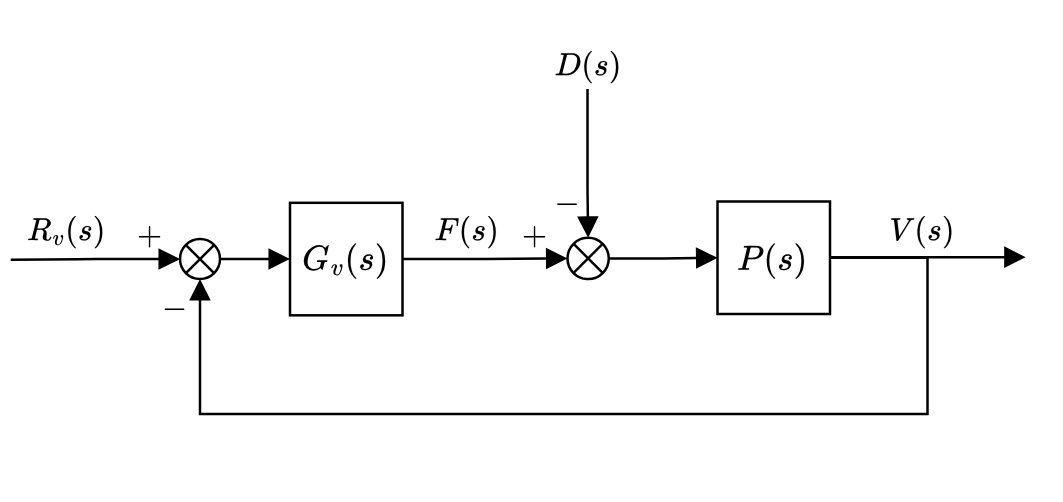

*Figure 4: Block diagram of minor loop that controls quadrotor velocity*.

Note that so far we have only defined specifications for the altitude controller (the outer loop effectively). Omitting gravity for now, we define our closed-loop velocity sub-system as

$T_v(s)=\frac{V(s)}{R_v(s)}=\frac{G_{v}(s)P(s)}{1+G_{v}(s)P(s)}=\frac{L_v(s)}{1+L_v(s)}$,

where $L_v(s)=G_v(s)P(s)$. We can then define specifications for $T_v(s)$ as follows: The inner (velocity) loop needs to be faster than our outer (altitude) loop, so we will set more aggressive specifications on our velocity loop, $T_v(s)$, for step reference signals, $R_v(s)=\frac{a}{s}$, of:

- **Settling time requirement: **$T_{v_s}\leq2.5$** seconds,**

- **Overshoot requirement: **$\%OS_v\leq 20\%$**,**

- **Steady-state error requirement: **$e_z(\infty)=0$,

- **Control action requirement: **$\min \{\lim_{s\rightarrow\infty}G_v(s)\}$.

Note that the velocity loop is required to be twice as fast as the altitude loop, but we are also allowing for twice the overshoot in the velocity system to achieve this. Minimising $\lim_{s\rightarrow\infty}G_v(s)$ is important, as a large high-frequency gain in our inner controller will end up amplifying the velocity sensor noise, which is not negligible in the `Simulink` simulation.

## Velocity feedback control

The simplest conceivable feedback controller is a proportional controller of the form $G_{v}(s)=K_v$, where $K_v\in\mathbb{R}^+$, but it does not solve our disturbance rejection problem and steady-state error requirement. You can see this by implementing the proportional control scheme on the *"real" *system with gravitational effects (the Simulink model), after synthesizing a suitable $K_v$ based on the transient velocity performance specifications. 

The next fundamental controller is the integral controller, which takes the form $G_{v}(s)=\frac{K_v}{s}$. However, there is a problem with this configuration in the case of controlling the quadrotor velocity. Specifically, the $90^\circ$ phase lag and gain roll-off contributed by the integrator makes achieving our closed-loop specifications impossible for certain mass and damping coefficient combinations (which varies depending on your PeopleSoft number). Effectively, we would not be able to make our closed-loop system faster than our open-loop system. 

A more robust solution to controlling the velocity is to use a controller with a single integrator *and* negative-real zero, which is known as a **proportional-plus-integral controller, **or PI controller

$G_v(s)=K_v\frac{1+sT_i}{sT_i}$,

where $\{K_v,T_i\} \in \mathbb{R}^+$.

The name stems from the fact that a PI controller is made up by summing a proportional and integral controller, namely

$G(s)=K\frac{1+sT_i}{sT_i}=K+\frac{K}{T_is}$.

The PI controller contains a single pole, located at $p=0$ (the origin in the $s$-plane), and a single zero, located at $z=\frac{-1}{T_i}$.

Using the two-term representation above, and noting that the control action is given by $U(s)=G_v(s)E(s)$, the relationship between tracking error and control action in the time-domain is obtained as

$u(t)=K_ve(t)+\frac{K_v}{T_i}\int_{0}^te(t)\delta t$.

The PI controller therefore makes use of an integrator, which continually increases control action $u(t)$, via the term $K_v\int_{0}^te(t)$, until such time that $e(t)=0$. The term $T_i$ is known as the integral time constant, as decreasing $T_i$ increases the gain of the integrator term, $\frac{K_v}{T_i}\int_{0}^te(t)\delta t$.

The PI controller makes use of a pole at $s=0$ to simultaneously reject disturbances at steady-state, and to meet the general requirement of having at least a Type-1 system to achieve zero-error step reference tracking at steady-state. Additionally, a zero in the controller is used to counteract the gain and phase drop-off at high frequencies. The PI controller will therefore act like a pure integrator with gain at low frequencies, and appear as a constant gain at high frequencies. This controller contributes infinitely large gain at DC based on $\lim_{s\rightarrow 0}G_v(s)=\infty$, and it contributes finite gain at high frequencies based on $\lim_{s\rightarrow \infty}G_v(s)=K_v$. This allows for an easier design in turns of satisfying stability margins, whilst benefitting from the integrator at low frequencies.

####  **  Task:** Design a proportional-plus-integral controller, $G_v(s)=K_v\frac{1+sT_i}{sT_i}$, that simultaneously meets all the specifications defined for the inner (velocity) loop, $T_v(s)$.

- Use the design approach outlined in Chapter 12 of the course notes.

- The design process should not come down to guessing correct parameters!

- Use your model approximation in this live script — do not use Simulink just yet.

- Use a lower bound magnitude of $M_B=0.98$ (or approximately $-0.18$ dB)

- In order to use functions such as `nichols`, `stepinfo`, `margins`, etc, you must use `s=tf('s')` in `MATLAB `when defining your Laplace variable, e.g:

#### **  Question 3: Determine the 2nd-order reference model, **$M_A(s)$, that meets the design specifications defined for the velocity loop control, namely $T_v(s)$.

*    Format: Your answer should show the necessary working and can be handwritten or mathematically typeset. *

%Add code here for Question 3 (if required)


#### **  Question 4: Determine the simplified below bound, **$M_A$ in $dB$. 

*     Format: Your answer should be a numerical value.*

%Add code here for Question 4 (if required)


#### **  Question 5: Determine the peak frequency of the reference model, **$\omega_p$, in $rad/s$.

*    Format: Your answer should be a numerical value.*

%Add code here for Question 5 (if required)


#### **  Question 6: Output a log-polar plot demonstrating your design approach to meet the **design specifications defined for the velocity loop control, namely $T_v(s)$**. Ensure your log-polar plot displays the relevant design boundary regions, the frequency response locus of **$L_v(j\omega)$, and the reference peak frequency, $\omega_p$, highlighted.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Log-polar plot_SMTJOH999.*

*Hint 1: If you click on an image, there is an Export option that allows you to save the image.*

%Add code here for Question 6 (if required)


#### **  Question 7: Output the selected PI controller gain, **$K_v$, that meets the performance objectives defined for the inner (velocity) loop controller, $T_v(s)$. 

*    Format: Your answer should be numerical values.*

%Add code here for Question 7 (if required)


#### **  Question 8: Output the selected PI controller integral time constant, **$T_i$, that meets the performance objectives defined for the inner (velocity) loop controller, $T_v(s)$. 

*    Format: Your answer should be numerical values.*

%Add code here for Question 7 (if required)


#### **  Question 9: Output a step response of the quadrotor** velocity, $v(t)$, for a step reference velocity of $5$m.s$^{-1}$, applied at $t=0$ seconds.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Step response_SMTJHN001.*

%Add code here for Question 8 (if required)


We can verify that our PI controller is working on the *"real"* system by implementing it in the Simulink environment.

####  **  Task: **Apply a velocity step reference of $r_v=20$m.s$^{-1}$ to the *"real"* quadrotor system (after feeding back the velocity measurement and including your PI controller). 

The simulink setup should be setup as shown below. Note this is equivalent in structure to *Figure 4 *when $G_v(s)=K\frac{1+sT_i}{sT_i}$.

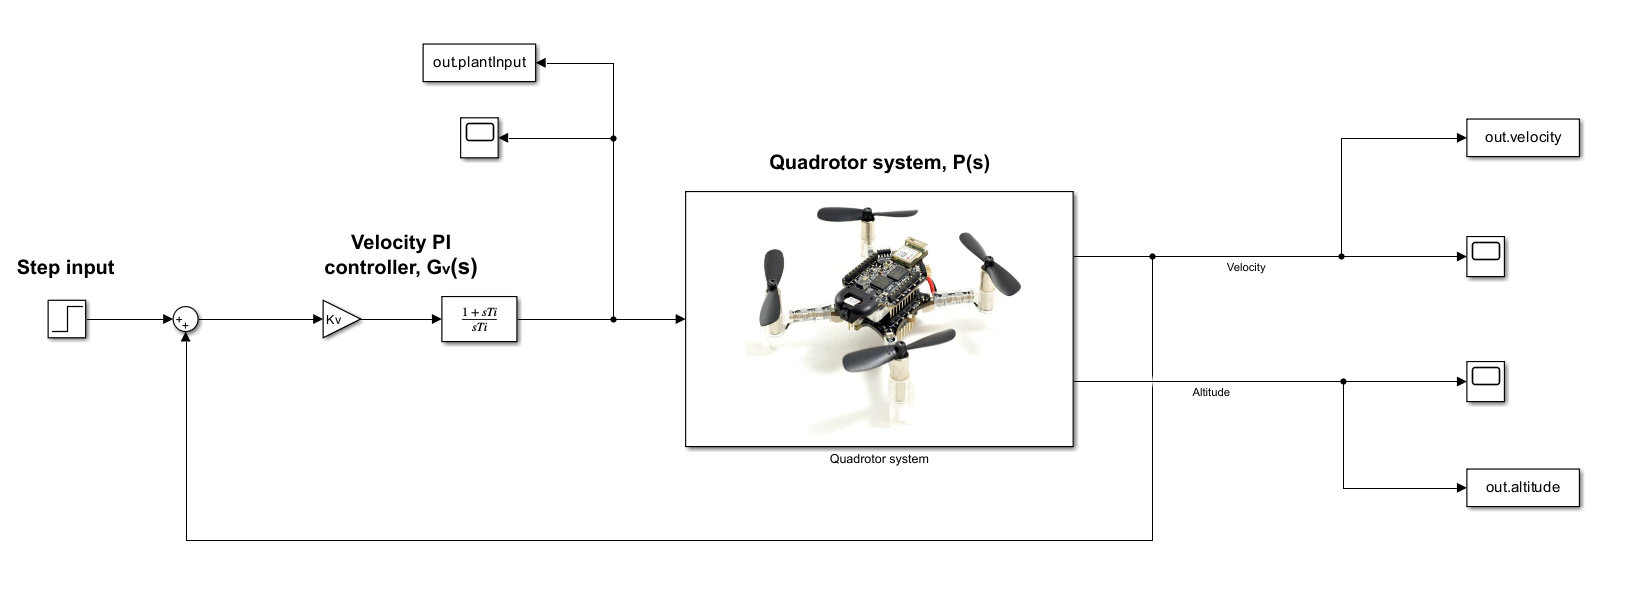

*Figure 5: Simulink environment of the the implemented velocity feedback controller, *$G_v(s)$,* on the "real" quadrotor system*

The block used for the zero and integrator in the figure above is called a [`Transfer Fcn`](https://www.mathworks.com/help/simulink/slref/transferfcn.html?searchHighlight=transfer%20fcn&s_tid=srchtitle_transfer%20fcn_1) block, and the block representing the $K_v$ term is called a [`Gain`](https://www.mathworks.com/help/simulink/slref/gain.html) block*. *Alternatively, you could also use a [`LTI System`](https://www.mathworks.com/help/control/ref/ltisystem.html?searchHighlight=lti%20system&s_tid=srchtitle_lti%20system_1) block to represent the entire PI controller, which can be setup to use the $G_{v}(s)$ that you define in this live script. An example of this is shown below.

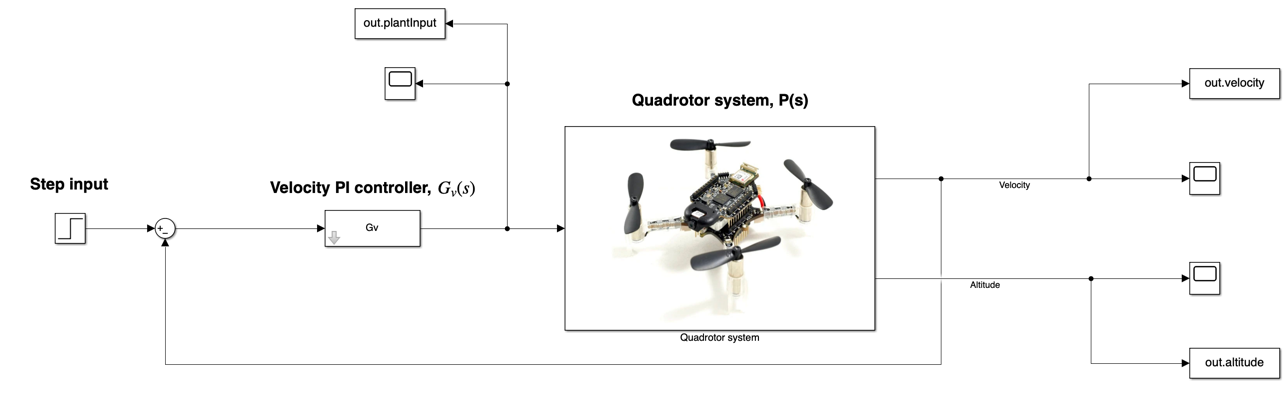

What you should see is that applying a step reference signal from initial conditions may have a larger settling time than expected, but subsequent steps applied after the quadrotor reaches steady-state (within the same simulation) will have the correct transient behaviour. This is because during the first step, the integrator was required to wind up (accumulate) in order to offset the constant gravitational force value. Once the first step response reaches steady-state, the integrator will have completely cancelled out the effect of gravity (by effectively applying an equivalent gravitational force in the upward direction) and subsequent responses follow the theoretical results. 

#### **  Question 10: Output** a step response of the *"real"* quadrotor system velocity, $v(t)$, for a step of $10$m.s$^{-1}$, applied at $t=0$ seconds, followed by a second step of $-10$m.s$^{-1}$, applied at $t=10$ seconds, resulting in a final velocity reference of $0$m.s$^{-1}$.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Step response_SMTJHN001.*

%Add code here for Question 9 (if required)


## Altitude feedback control

If you are happy with your PI velocity controller, $G_v(s)$, in that it meets the inner (velocity) control loop specifications, we can then move onto the outer loop design — the altitude control loop, $G_z(s)$. Based on *Figure 2,* repeated below for sake of convenience,

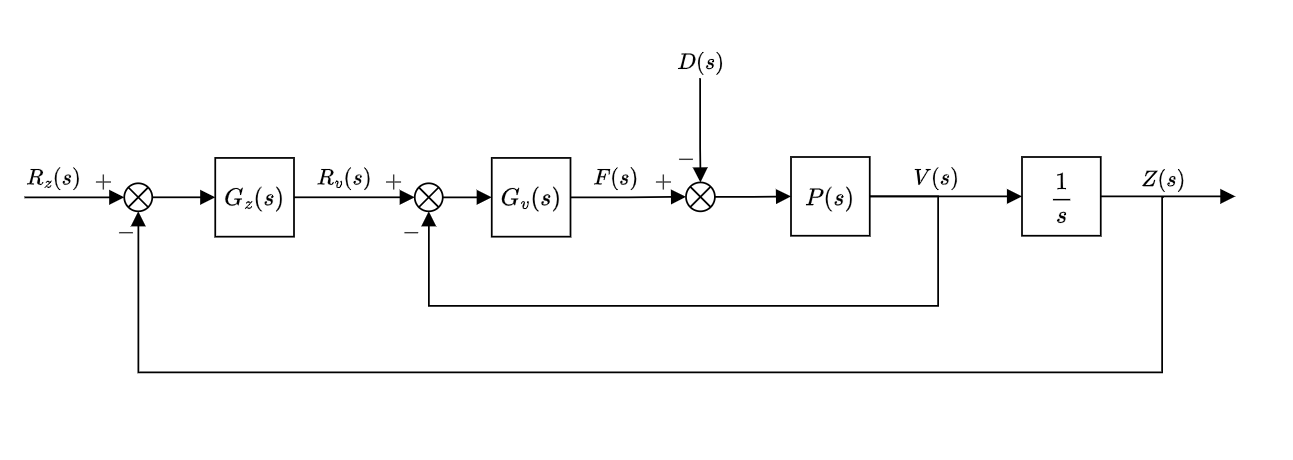

*Figure 5: Block diagram of the cascaded closed-loop quadrotor system. Sensor noise has been excluded from the block diagram for sake of clarity.*

the open-loop altitude control system is simply:

$P_z(s)=\frac{T_v(s)}{s}=\frac{G_{v}(s)P(s)}{s(1+G_{v}(s)P(s))}=\frac{L_v(s)}{s(1+L_v(s))}$.

We will design a proportional controller, $G_{z}(s)=K_p$, for our outer loop, as the PI controller in the velocity loop will ensure that our gravitational disturbance is kept in check. As a reminder, our altitude loop specifcations are:

- $T_{z_s}<5$seconds,

- $\%OS_{z} < 10\%$,

- $e_z(\infty)=0$,

- $\min \{F(t)\}$.

####  **  Task:** Design a proportional controller, $G_{z}(s)=K_z$, that meets all the requirements above, whilst also minimising $F(t)$.

- Use the design approach outlined in Chapter 12 of the course notes.

- The design should not come down to guessing correct parameters!

- Use your model approximation in this live script — do not use Simulink just yet.

- Use a lower bound magnitude of $M_B=\frac{1}{\sqrt2}=0.707$, (or approximately $-3.01$ dB).

- In order to use functions such as `nichols`, `stepinfo`,` margins`, etc, you must use `s=tf('s')` in `MATLAB `when defining your Laplace variable, e.g:

#### **  Question 11: Determine the 2nd-order reference model natural frequency, **$\omega_n$, that meets the design specifications for the quadrotor altitude feedback control.

*    Format: Your answers should be numerical values, rounded to two decimal places. *

%Add code here for Question 11 (if required)


#### **  Question 12: Determine the 2nd-order reference model damping ratio, **$\zeta$, that meets the design specifications for the quadrotor altitude feedback control.

*    Format: Your answers should be a numerical, rounded to two decimal places. *

%Add code here for Question 12 (if required)


#### **  Question 13: Determine the desired closed-loop bandwidth frequency, **$\omega_0$, in $rad/s$, of the *stay-above bound, *$M_B$.

*    Format: Your answer should be a numerical value.*

%Add code here for Question 13 (if required)


#### **  Question 14: Determine the simplified below bound, **$M_A$ in $dB$.

*     Format: Your answer should be a numerical value.*

%Add code here for Question 14 (if required)


#### **  Question 15: Output a log-polar plot demonstrating your design approach. Ensure your log-polar plot displays the relevant design boundary regions, the frequency response locus of **$L_z(j\omega)$, and the desired closed-loop bandwidth frequency, $\omega_0$, highlighted.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Log-polar plot_SMTJHN001.*

%Add code here for Question 15 (if required)


#### **  Question 16: Output the selected controller parameter, **$K_z$, that meets the performance objectives defined for the outer (altitude) loop controller. 

*    Format: Your answer should be a numerical value.*

%Add code here for Question 16 (if required)


#### **  Question 17: Output a step response of the quadrotor** altitude, $z(t)$, for a step of $5$metres, applied at $t=0$ seconds.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Step response_SMTJHN001. *

%Add code here for Question 17 (if required)


We can verify that our altitude controller is working on the *"real"* system by implementing it in the Simulink environment.

####  **  Task: Implement the altitude control** system (after feeding back the velocity and altitude measurements appropriately and including your PI and proportional controllers). 

The simulink setup should be setup as shown below. Note this is equivalent in structure to *Figure 2 *when $G_v(s)=K_v\frac{1+sT_i}{sT_i}$ and $G_{z}(s)=K_z$.

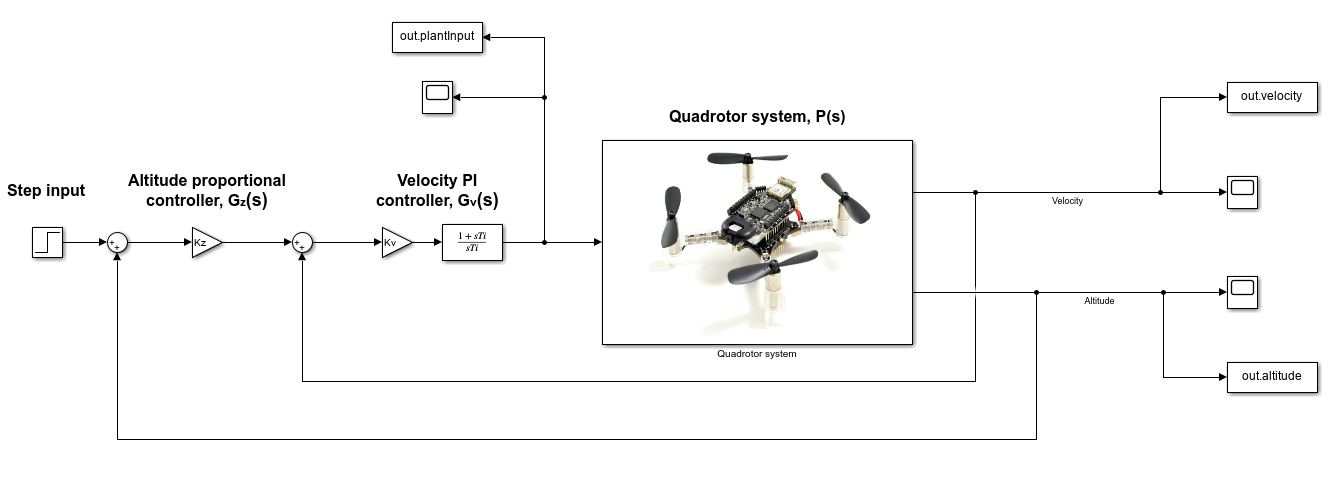

*Figure 6: Simulink environment of the implemented altitude and velocity feedback controller, *$G_z(s)$ and $G_v(s)$ *respectively*,* on the "real" quadrotor system*

As with the velocity step testing, the integrator is first required to accumulate appropriately, but once that has been completed, subsequent step responses should match up with the estimated behaviour. You can scope the force input to confirm this — what you should see is that the force input tends to the gravitational force, $mg$, at steady-state.

#### **  Question 18: Output a step response** of the *"real"* quadrotor system altitude, $z(t)$, for a unit step of $1$ metre, applied at $t=0$ seconds, followed by a second unit step, applied at $t=10$ seconds.

    *Format: Your answer should be a figure (.png or .jpeg) with your student number appended onto the title, eg: Step response_SMTJHN001.*

%Add code here for Question 18 (if required)


#### **  Question 19: **Upload your final Project.mlx script *and* Project.slx. Ensure that both files have your student numbers appended to the files names, e.g. Project_SMTJOH999.slx.

*This concludes the project.*